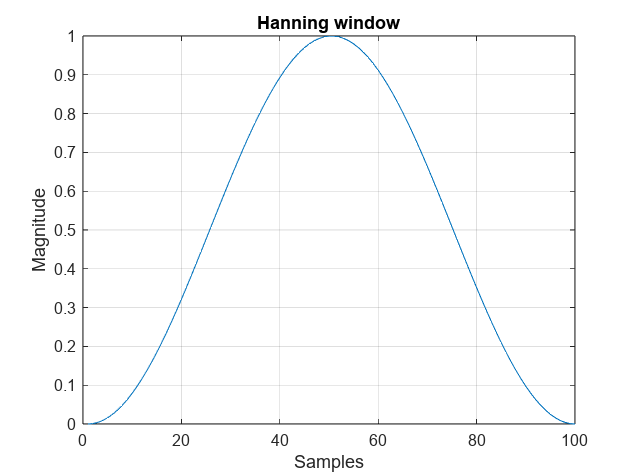

%Questioni 1;
% A
figure;
plot(hann(100));
xlabel("Samples")
ylabel("Magnitude")
title("Hanning window")

grid on

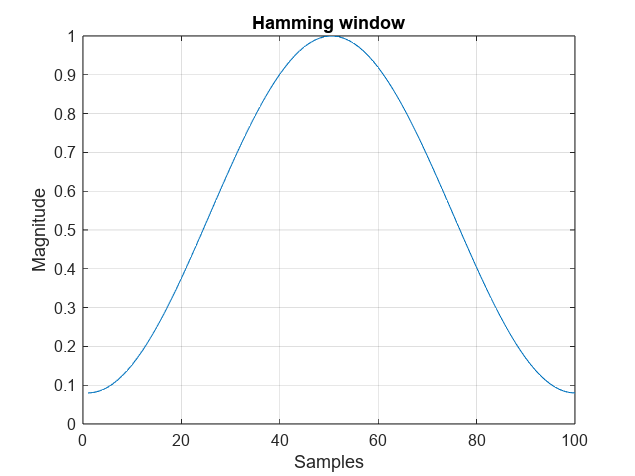

figure;
plot(hamming(100));
xlabel("Samples")
ylabel("Magnitude")
title("Hamming window")

grid on

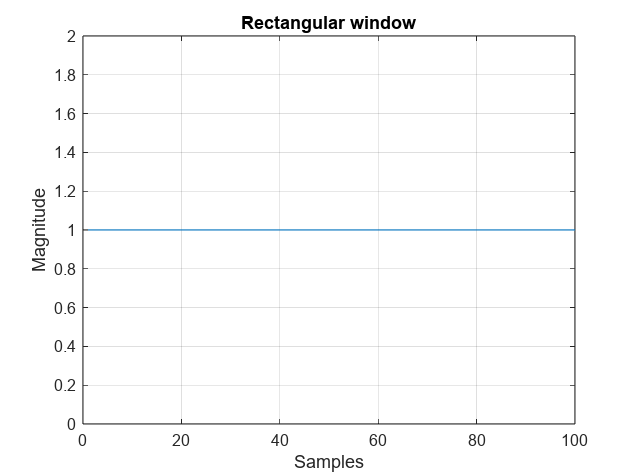


figure;
plot(rectwin(100));
xlabel("Samples")
ylabel("Magnitude")
title("Rectangular window")

grid on

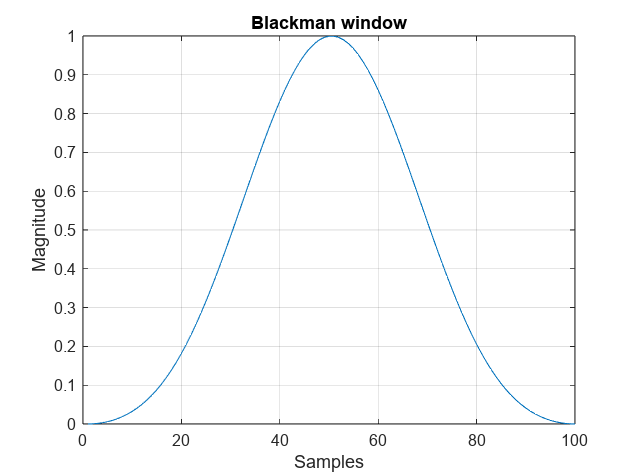


%b
figure;
plot(blackman(100));
xlabel("Samples")
ylabel("Magnitude")
title("Blackman window")

grid on

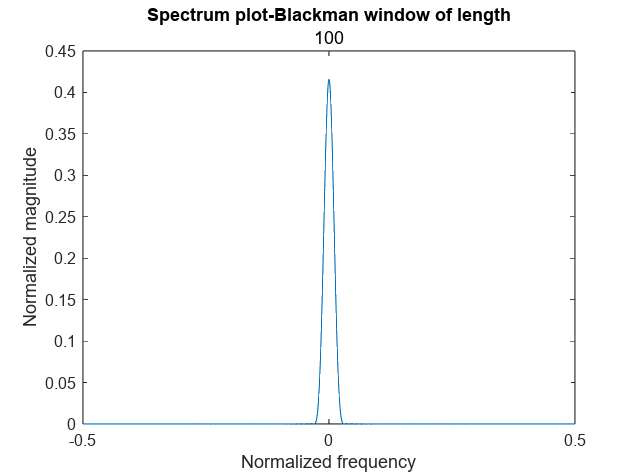

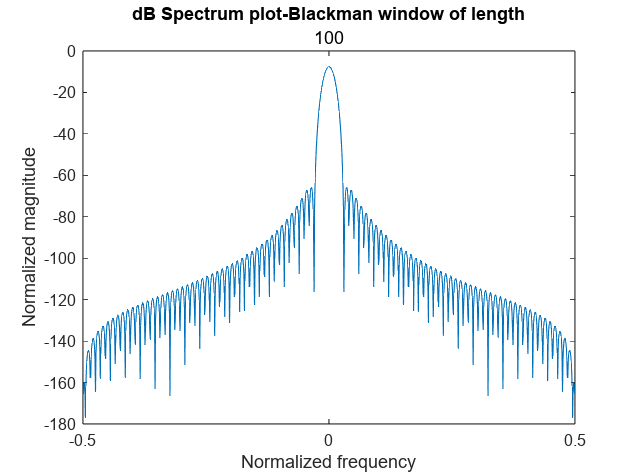

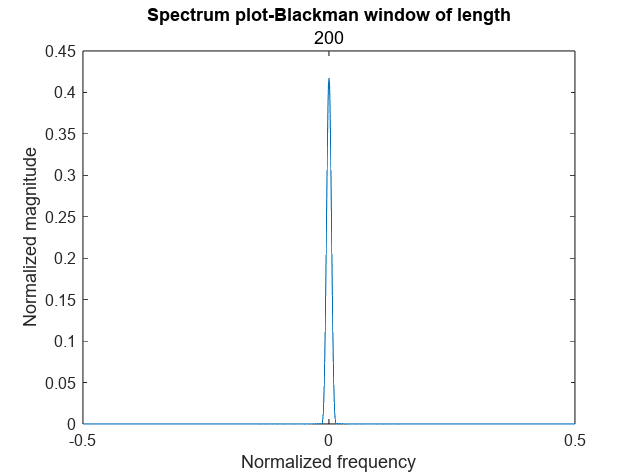

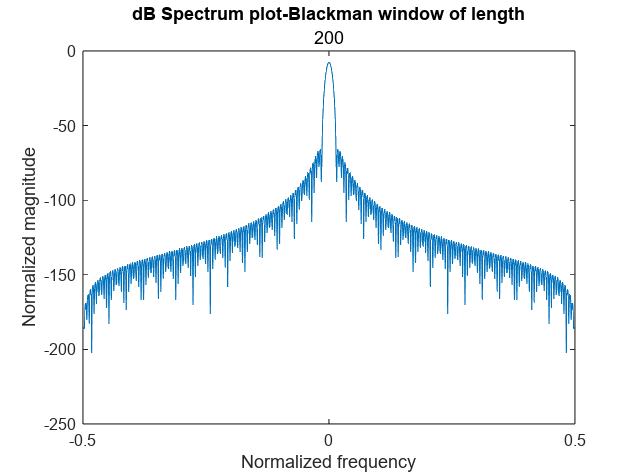

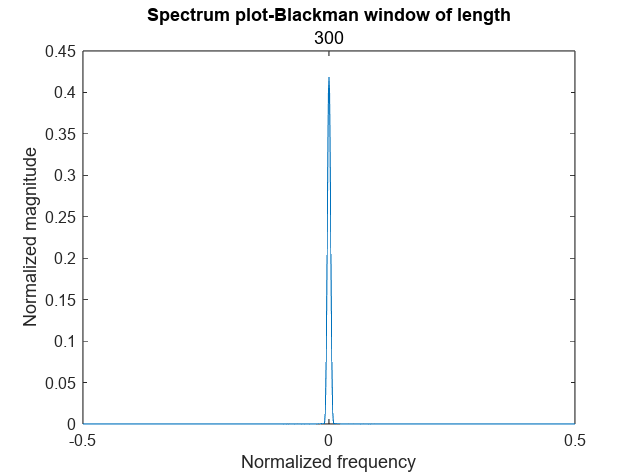

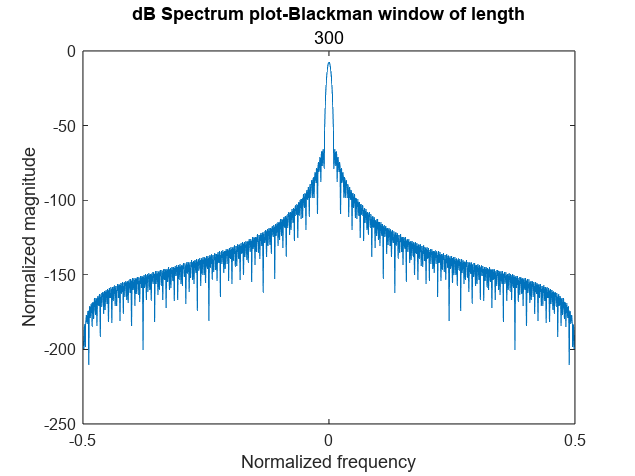


N=[100,200,300];
for i=1:3
    y1=abs(fftshift(fft(blackman(N(i)),1024)))/N(i);
    f1=(-1024/2:1024/2-1)./length(y1);
    %f1=linspace(0,Fs,1024);
    figure;
    plot(f1,(y1));
    xlabel("Normalized frequency");
    ylabel("Normalized magnitude");
    title("Spectrum plot-Blackman window of length", num2str(N(i)))
    figure;
    plot(f1,(db(y1)))
    xlabel("Normalized frequency");
    ylabel("Normalized magnitude");
    title("dB Spectrum plot-Blackman window of length", num2str(N(i)))
end

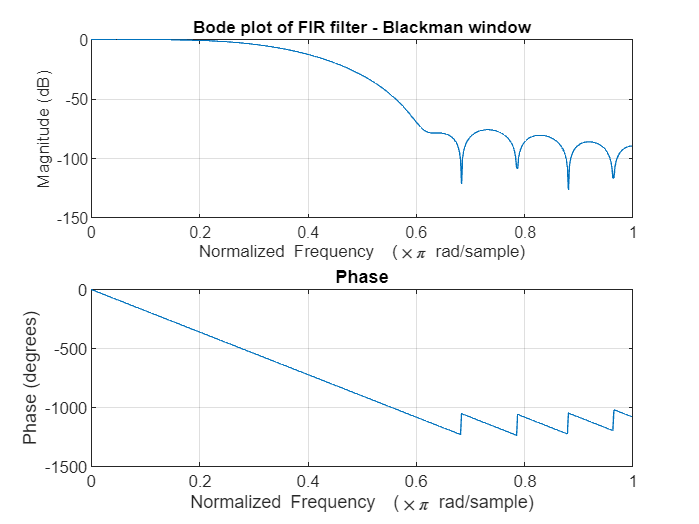




%Question 2
y_black=fir1(20,1/3,"low",blackman(21));
figure;
freqz(y_black);
title("Bode plot of FIR filter - Blackman window")

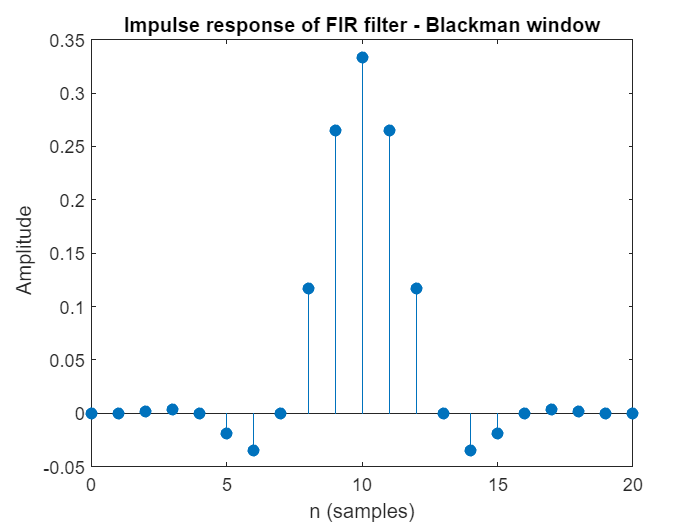

figure;
impz(y_black);
title("Impulse response of FIR filter - Blackman window")

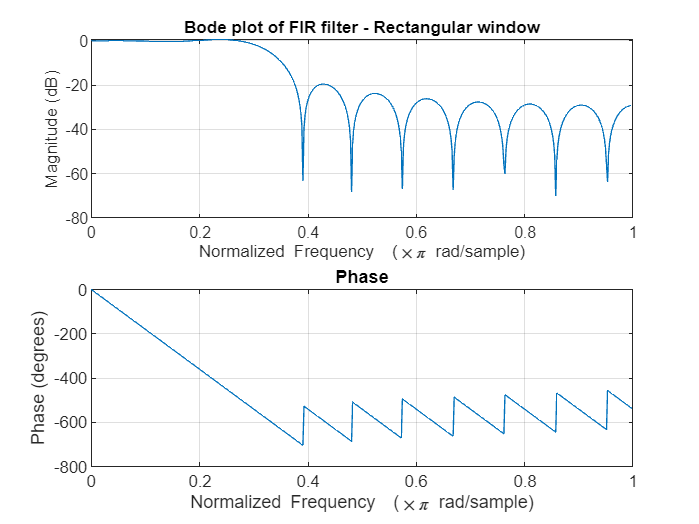

y_rect=fir1(20,1/3,"low",rectwin(21));
figure;
freqz(y_rect);
title("Bode plot of FIR filter - Rectangular window")

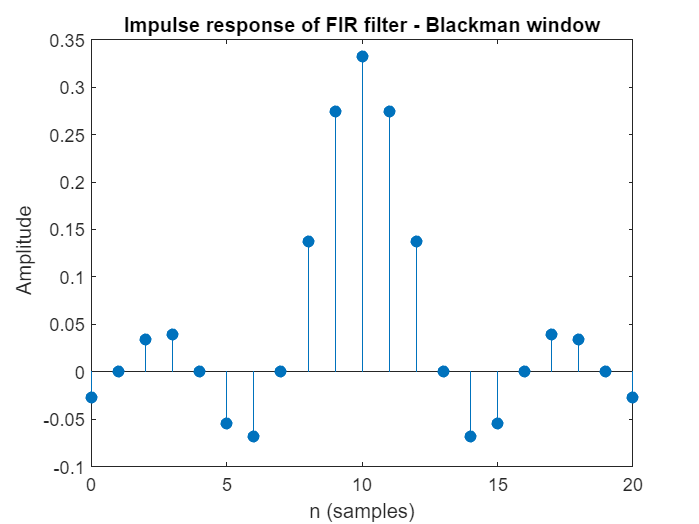

figure;
impz(y_rect);
title("Impulse response of FIR filter - Blackman window");

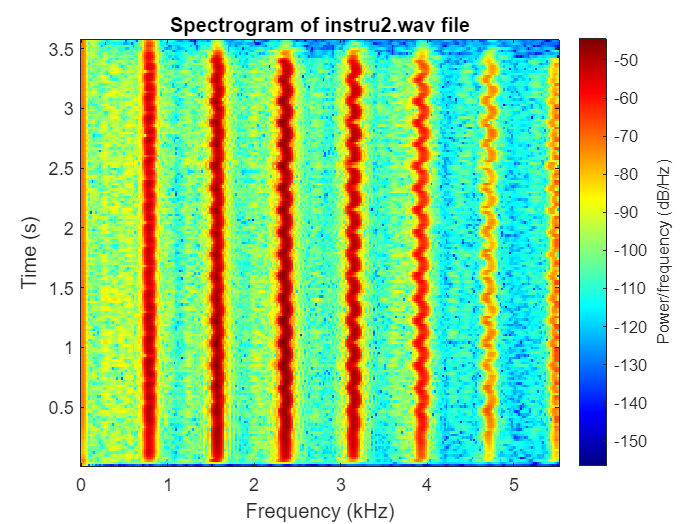


%Question 3
[ins,fs]=audioread("instru2.wav");
figure;
spectrogram(ins,hann(256),20,512,fs);
colormap jet
zlabel("Magnitude");
title("Spectrogram of instru2.wav file");

% y=fir1(255,2*650/fs,"bandpass",hann(256))
y=fir1(255,[1200/fs 2*900/fs],"bandpass",hann(256),"scale")

y =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0002    0.0003    0.0003    0.0003    0.0003    0.0001   -0.0002   -0.0005   -0.0008   -0.0009   -0.0009   -0.0007   -0.0003    0.0002    0.0008    0.0012    0.0015    0.0014    0.0012    0.0006   -0.0000   -0.0007   -0.0011   -0.0014   -0.0013   -0.0010   -0.0006


yfilter=filter(y,1,ins)

yfilter =          0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000


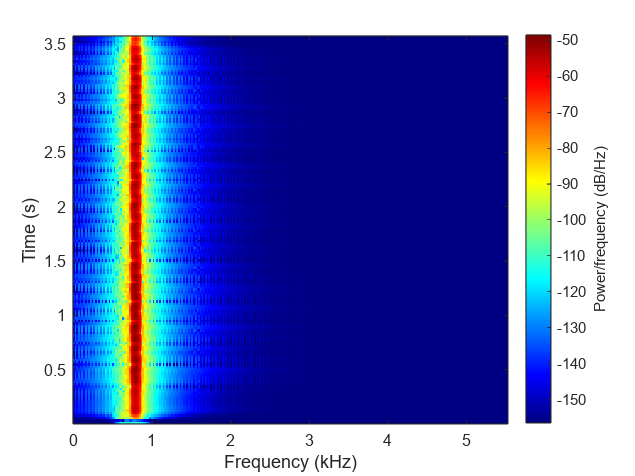

figure;
spectrogram(yfilter,hann(256),10,512,fs);

colormap jet;